## 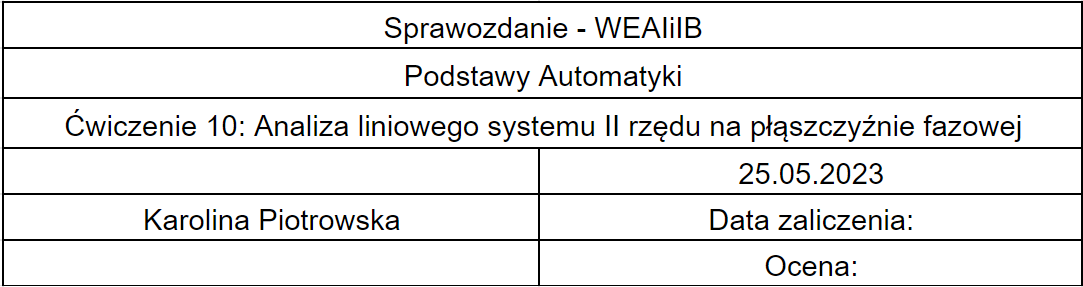

## Wstęp teoretyczny

Metoda płaszczyzny fazowej polega na poszukiwaniu wozwiązania dynamicznego równania ruchu nie jako funkcji czasu, lecz w postaci zależności między prędkością a przemieszczeniem. Metoda płaszczyzny fazowej pozwala określić podstawowe właściwości ruchu bez potrzeby rozwiązywania wyjściowych równań ruchu w dziedzinie czasu. Najwygodniej jest ją stosować, gdy dysponuje się maszyną analagową z ploterem lub oscyloskopem.

## Przebieg laboratorium

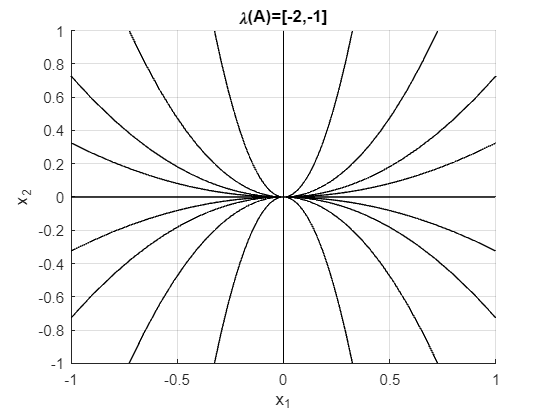

%skrypt do generowania trajektorii fazowych:
%Nazwa do wywołania: tr_faz
%Tu wpisujemy macierz stanu:
A = [-1, 0; 0, -2];
T = 6; %czas końcowy
[w J] = eig(A); %wektory i wartości własne
figure; hold on; grid on;
%Wyznaczanie zbioru warunków poczakowych obejmujących wszystkie 4 ćwiartki
%płaszczyzny fazowej:
a=0:(pi/10):(2*pi);X1=[cos(a);sin(a)];
%cykliczne wywoływanie modelu simulinkowego wraz rysowaniem trajektorii:
X2=X1./[max(abs(X1));max(abs(X1))];M=size(X2,2);
for m=1:M
 x0=X2(:,m);
 sim('traj_fazowe',T); %W tym miejscu jest wykonywany model simulinkowy
 x = ans.x;
 plot(x(:,1),x(:,2),'k-');
 plot([0,w(1,1)],[0,w(2,1)],'k-',[0,w(1,2)],[0,w(2,2)],'k-');
 title(['\lambda(A)=[',num2str(J(1,1)),',',num2str(J(2,2)),']'] );
 xlabel('x_1');ylabel('x_2');
end

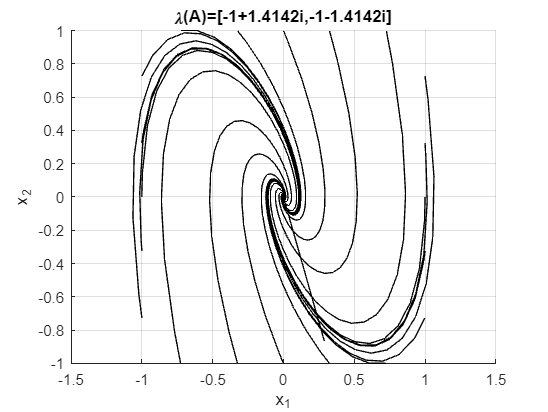

A = [0, 1; -3, -2];
T = 6; %czas końcowy
[w J] = eig(A); %wektory i wartości własne
figure; hold on; grid on;
%Wyznaczanie zbioru warunków poczakowych obejmujących wszystkie 4 ćwiartki
%płaszczyzny fazowej:
a=0:(pi/10):(2*pi);X1=[cos(a);sin(a)];
%cykliczne wywoływanie modelu simulinkowego wraz rysowaniem trajektorii:
X2=X1./[max(abs(X1));max(abs(X1))];M=size(X2,2);
for m=1:M
 x0=X2(:,m);
 sim('traj_fazowe',T); %W tym miejscu jest wykonywany model simulinkowy
 x = ans.x;
 plot(x(:,1),x(:,2),'k-');
 plot([0,w(1,1)],[0,w(2,1)],'k-',[0,w(1,2)],[0,w(2,2)],'k-');
 title(['\lambda(A)=[',num2str(J(1,1)),',',num2str(J(2,2)),']'] );
 xlabel('x_1');ylabel('x_2');
end

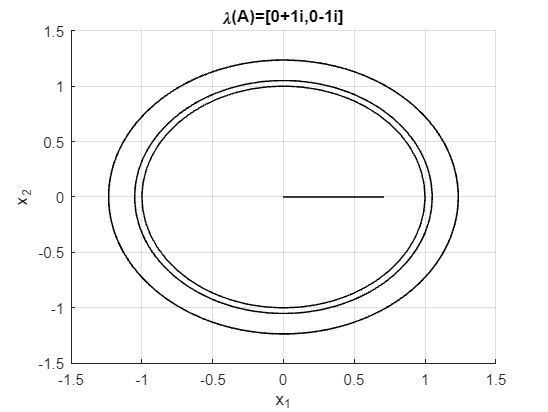

A = [0, 1; -1, 0];
T = 6; %czas końcowy
[w J] = eig(A); %wektory i wartości własne
figure; hold on; grid on;
%Wyznaczanie zbioru warunków poczakowych obejmujących wszystkie 4 ćwiartki
%płaszczyzny fazowej:
a=0:(pi/10):(2*pi);X1=[cos(a);sin(a)];
%cykliczne wywoływanie modelu simulinkowego wraz rysowaniem trajektorii:
X2=X1./[max(abs(X1));max(abs(X1))];M=size(X2,2);
for m=1:M
 x0=X2(:,m);
 sim('traj_fazowe',T); %W tym miejscu jest wykonywany model simulinkowy
 x = ans.x;
 plot(x(:,1),x(:,2),'k-');
 plot([0,w(1,1)],[0,w(2,1)],'k-',[0,w(1,2)],[0,w(2,2)],'k-');
 title(['\lambda(A)=[',num2str(J(1,1)),',',num2str(J(2,2)),']'] );
 xlabel('x_1');ylabel('x_2');
end

A = [0, 0; 0, -1];
T = 6; %czas końcowy
[w J] = eig(A); %wektory i wartości własne
figure; hold on; grid on;
%Wyznaczanie zbioru warunków poczakowych obejmujących wszystkie 4 ćwiartki
%płaszczyzny fazowej:
a=0:(pi/10):(2*pi);X1=[cos(a);sin(a)];
%cykliczne wywoływanie modelu simulinkowego wraz rysowaniem trajektorii:
X2=X1./[max(abs(X1));max(abs(X1))];M=size(X2,2);
for m=1:M
 x0=X2(:,m);
 sim('traj_fazowe',T); %W tym miejscu jest wykonywany model simulinkowy
 x = ans.x;
 plot(x(:,1),x(:,2),'k-');
 plot([0,w(1,1)],[0,w(2,1)],'k-',[0,w(1,2)],[0,w(2,2)],'k-');
 title(['\lambda(A)=[',num2str(J(1,1)),',',num2str(J(2,2)),']'] );
 xlabel('x_1');ylabel('x_2');
end

A = [0, 2; 0, -1];
T = 6; %czas końcowy
[w J] = eig(A); %wektory i wartości własne
figure; hold on; grid on;
%Wyznaczanie zbioru warunków poczakowych obejmujących wszystkie 4 ćwiartki
%płaszczyzny fazowej:
a=0:(pi/10):(2*pi);X1=[cos(a);sin(a)];
%cykliczne wywoływanie modelu simulinkowego wraz rysowaniem trajektorii:
X2=X1./[max(abs(X1));max(abs(X1))];M=size(X2,2);
for m=1:M
 x0=X2(:,m);
 sim('traj_fazowe',T); %W tym miejscu jest wykonywany model simulinkowy
 x = ans.x;
 plot(x(:,1),x(:,2),'k-');
 plot([0,w(1,1)],[0,w(2,1)],'k-',[0,w(1,2)],[0,w(2,2)],'k-');
 title(['\lambda(A)=[',num2str(J(1,1)),',',num2str(J(2,2)),']'] );
 xlabel('x_1');ylabel('x_2');
end

A = [0.5, 0; 0, -0.5];
T = 6; %czas końcowy
[w J] = eig(A); %wektory i wartości własne
figure; hold on; grid on;
%Wyznaczanie zbioru warunków poczakowych obejmujących wszystkie 4 ćwiartki
%płaszczyzny fazowej:
a=0:(pi/10):(2*pi);X1=[cos(a);sin(a)];
%cykliczne wywoływanie modelu simulinkowego wraz rysowaniem trajektorii:
X2=X1./[max(abs(X1));max(abs(X1))];M=size(X2,2);
for m=1:M
 x0=X2(:,m);
 sim('traj_fazowe',T); %W tym miejscu jest wykonywany model simulinkowy
 x = ans.x;
 plot(x(:,1),x(:,2),'k-');
 plot([0,w(1,1)],[0,w(2,1)],'k-',[0,w(1,2)],[0,w(2,2)],'k-');
 title(['\lambda(A)=[',num2str(J(1,1)),',',num2str(J(2,2)),']'] );
 xlabel('x_1');ylabel('x_2');
end

A = [0, 0.1; 0.2, 0];
T = 6; %czas końcowy
[w J] = eig(A); %wektory i wartości własne
figure; hold on; grid on;
%Wyznaczanie zbioru warunków poczakowych obejmujących wszystkie 4 ćwiartki
%płaszczyzny fazowej:
a=0:(pi/10):(2*pi);X1=[cos(a);sin(a)];
%cykliczne wywoływanie modelu simulinkowego wraz rysowaniem trajektorii:
X2=X1./[max(abs(X1));max(abs(X1))];M=size(X2,2);
for m=1:M
 x0=X2(:,m);
 sim('traj_fazowe',T); %W tym miejscu jest wykonywany model simulinkowy
 x = ans.x;
 plot(x(:,1),x(:,2),'k-');
 plot([0,w(1,1)],[0,w(2,1)],'k-',[0,w(1,2)],[0,w(2,2)],'k-');
 title(['\lambda(A)=[',num2str(J(1,1)),',',num2str(J(2,2)),']'] );
 xlabel('x_1');ylabel('x_2');
end

A = [0, 0; 0, 1];
T = 6; %czas końcowy
[w J] = eig(A); %wektory i wartości własne
figure; hold on; grid on;
%Wyznaczanie zbioru warunków poczakowych obejmujących wszystkie 4 ćwiartki
%płaszczyzny fazowej:
a=0:(pi/10):(2*pi);X1=[cos(a);sin(a)];
%cykliczne wywoływanie modelu simulinkowego wraz rysowaniem trajektorii:
X2=X1./[max(abs(X1));max(abs(X1))];M=size(X2,2);
for m=1:M
 x0=X2(:,m);
 sim('traj_fazowe',T); %W tym miejscu jest wykonywany model simulinkowy
 x = ans.x;
 plot(x(:,1),x(:,2),'k-');
 plot([0,w(1,1)],[0,w(2,1)],'k-',[0,w(1,2)],[0,w(2,2)],'k-');
 title(['\lambda(A)=[',num2str(J(1,1)),',',num2str(J(2,2)),']'] );
 xlabel('x_1');ylabel('x_2');
end

## Wnioski

Ćwiczenie pozwoliło zapoznać się z zachowaniami różnych układów na płaszczyźnie fazowej.

- Układ stabilny aperiodycznie: linie wykresu zmierzają do środka układu - obiekt wytrącony z równowagi wraca do niej

- Układ stabilny oscylacyjny tłumiony: zmierza do punktu równowagi, lecz wolniej niż poprzedni. Przebieg oscyluje ze stałą amplitudą wokół punktu równowagi, ale nie zmierza do niego

- Dwa kolejne układy różnią się zmienną, która jest całkowana

- Trzy istatnie układy są niestabilne - po wytrąceniu z punktu równowagi nie wracają do niego.